 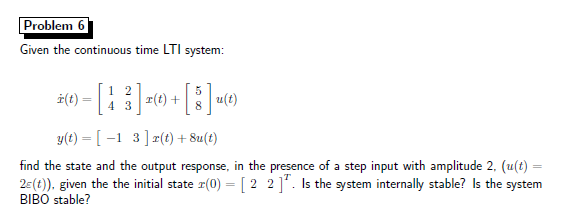

A=[1 2;4 3];
B=[5 8]';
C=[-1 3];
D=[8];
x0=[2 2]';
sys=ss(A,B,C,D);

s=tf('s');
H=tf(sys)   %da u in y transfer function

H =
 
  8 s^2 - 13 s - 5
  ----------------
   s^2 - 4 s - 5
 
Continuous-time transfer function.



U=2/s;
Y=minreal((zpk(C*inv(s*eye(2)-A)*B*U+D*U)),1e-3)

Y =
 
  16 (s-1.946) (s+0.3211)
  -----------------------
       s (s-5) (s+1)
 
Continuous-time zero/pole/gain model.



[numY,denY]=tfdata(Y,'v')  %v because I need a vectorial format

numY =          0   16.0000  -26.0000  -10.0000


denY =     1.0000   -3.9996   -5.0001         0



[r,p]=residue(numY,denY) %the residues are the numerators and p are the poles

r =     8.6661
    5.3339
    2.0000


p =     4.9997
   -1.0001
         0




pole(H)

ans =      5
    -1


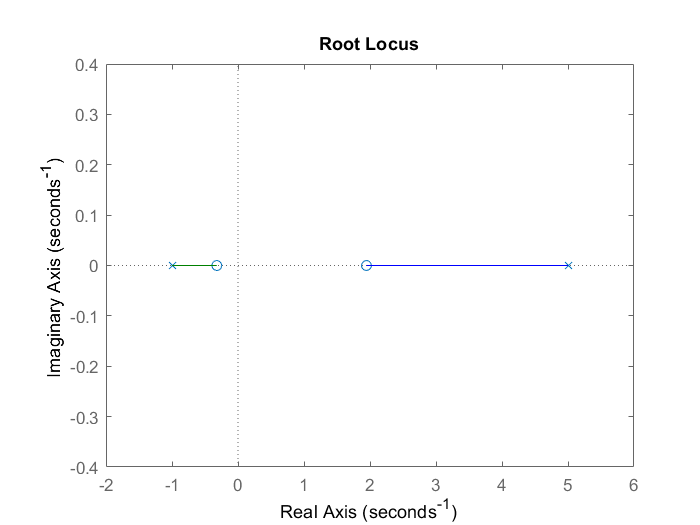

rlocus(H)

There is a positive eigenvalue so the system is unstable and divergent.

## **SYMBOLIC METHOD**

H

$$H = \frac{-8\,s^{2}+13\,s+5}{-s^{2}+4\,s+5}$$

clear
syms t f(t) H s

H=(8*s^2-13*s-5)/((s^2-4*s-5))

$$H = \frac{-8\,s^{2}+13\,s+5}{-s^{2}+4\,s+5}$$

f(t)=piecewise(t<0, 0,t>=0,2)

$$f(t) = \left\{ \begin{array}{cl} 0 & \text{ if }t<0\\ 2 & \text{ if }0\leq t \end{array}\right.$$


assume(t,'positive')
y=vpa(simplify(ilaplace(laplace(f)*H)),4)

$$y = 5.333\,{\mathrm{e}}^{-1.0\,t}+8.667\,{\mathrm{e}}^{5.0\,t}+2.0$$

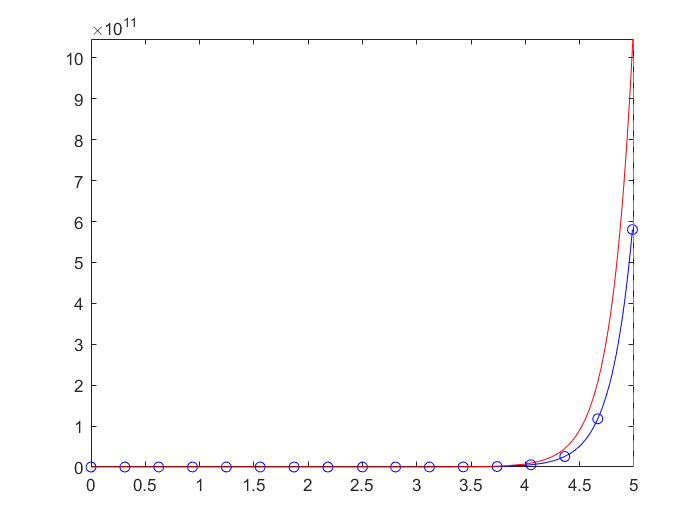

fplot(y,'b-o')
hold on
fplot(15.3*exp(5*t)+2.6*exp(-t)+2,'r')
hold off